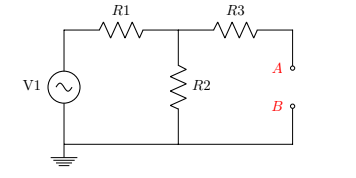

**calculamos el equivalente thevenin**

clc, clear, close all
format short g

vf = 5; %rms
r1 = 50;
r2 = 30;
r3 = 100;

zeq = r1+r2

zeq =     80


If = vf/zeq %[A] rms

If =        0.0625


vth = If*r2 %tension thevenin

vth =         1.875


vth_max = vth*sqrt(2)

vth_max =        2.6517


corriente norton

syms i1 i2

ec1= simplify(vf+(r1*i1)+r2*(i1-i2) == 0)

$$ec1 = 6\,i_{2}=16\,i_{1}+1$$

ec2= simplify(r2*(i2-i1)+r3*i2 == 0)

$$ec2 = 3\,i_{1}=13\,i_{2}$$

m = [-16 6; 3 -13];
n = [1;0];
h = m\n

h =     -0.068421
    -0.015789


In = h(2) %[A] rms

In =     -0.015789


rth = vth/In

rth =       -118.75


Equivalente thevenin

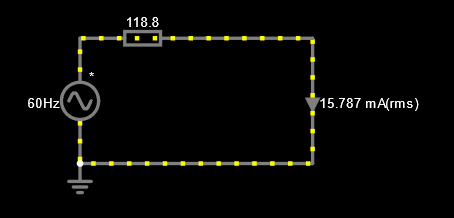

**Diseño 1:**

**Circuito RL diseño para angulo de -70°**

l = 5e-3;
r = 118.75;
vf = 5; %rms

syms angulo f L R

ec1 = solve(tan(angulo)==(2*pi*f*L)/R,f)

$$ec1 = \frac{R\,\tan\left(\mathrm{angulo}\right)}{2\,L\,\pi }$$

f = abs((r*tand(-70))/(2*l*pi)) %frecuencia necesaria 

f =         10385


Asi obtenemos la frecuencia necesaria para obtener un desfase de -70 grados en la correinte del inductor, lo verificamos en el simulador:

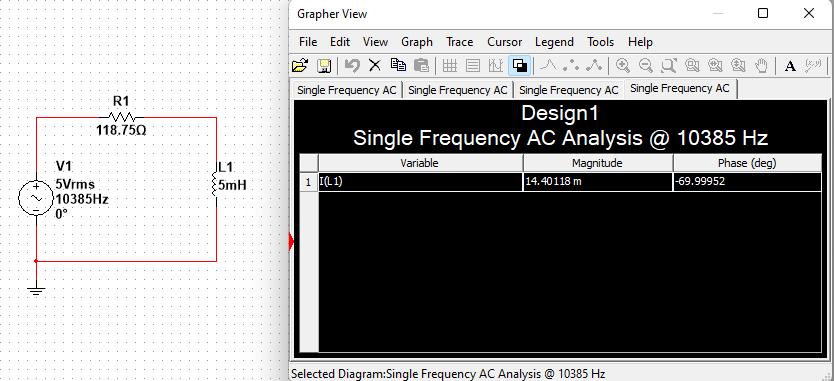

ya que sabemos la frecuencia calculamos la corriente y tension en el inductor:

xl = (2*pi*f*l)*j

xl =             0 +     326.26i


zrl = r + xl

zrl =        118.75 +     326.26i


Il = vf/zrl;
Il_fasor = [abs(Il) angle(Il)*180/pi] %fasor corriente en el inductor [A]

Il_fasor =      0.014401          -70


vl = Il*(xl);
vl_fasor = [abs(vl) angle(vl)*180/pi] %fasor voltaje en el inductor

vl_fasor =        4.6985           20


verificamos en el simulador:

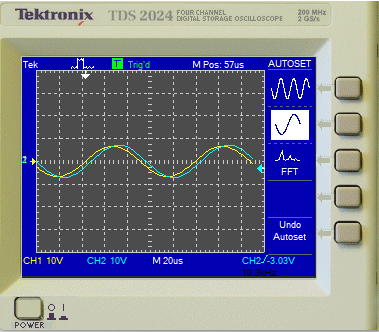

tension de la fuente (amarillo) comparada con la tension en el inductor (azul)

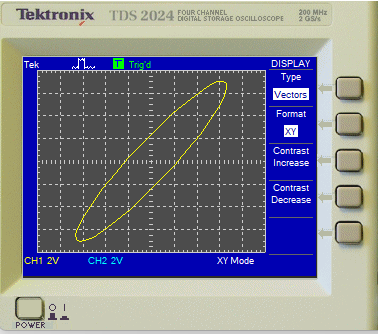

figura de lissajous

*Diagrama fasorial*

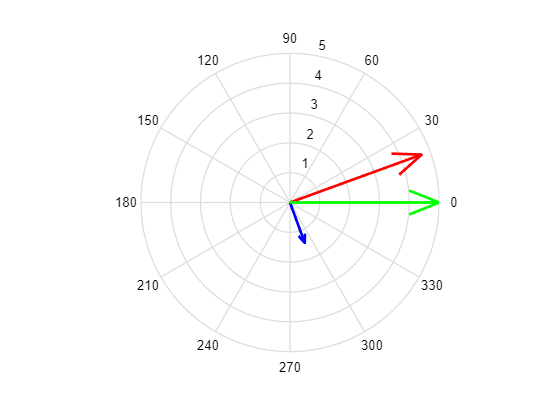

u = [real(vl) real(Il)*1e2 real(vf)];
v = [imag(vl) imag(Il)*1e2 imag(vf)];
co = compass(u,v);
c1 = co(1);
c1.LineWidth = 2;
c1.Color = 'r';
c2 = co(2);
c2.LineWidth = 2;
c2.Color = 'b';
c3 = co(3);
c3.LineWidth = 2;
c3.Color = 'g';

diagrama fasorial, tension de la fuente (verde), tension en el inductor (rojo), corriente en el indcutor (azul)

**Circuito RL diseño para -20°**

f = abs((r*tand(-20))/(2*l*pi)) %frecuencia necesaria 

f =        1375.8


verificamos en el simulador:

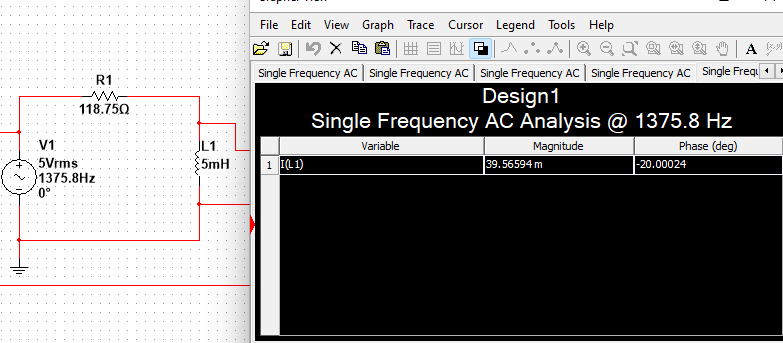

calculamos correintes y tensiones en el inductor:

xl = (2*pi*f*l)*j

xl =             0 +     43.221i


zrl = r + xl

zrl =        118.75 +     43.221i


Il = vf/zrl;
Il_fasor = [abs(Il) angle(Il)*180/pi] %fasor corriente en el inductor [A]

Il_fasor =      0.039566          -20


vl = Il*(xl);
vl_fasor = [abs(vl) angle(vl)*180/pi] %fasor voltaje en el inductor

vl_fasor =        1.7101           70


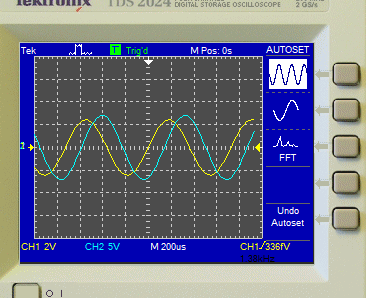

tension de la fuente (amarillo) comparada con la tension en el inductor (azul)

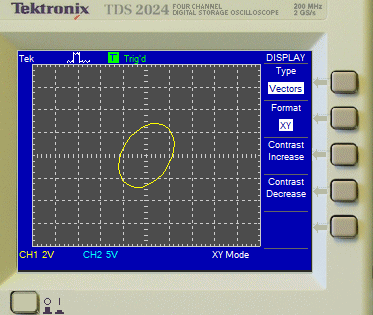

figura de lissajous

diagrama fasorial

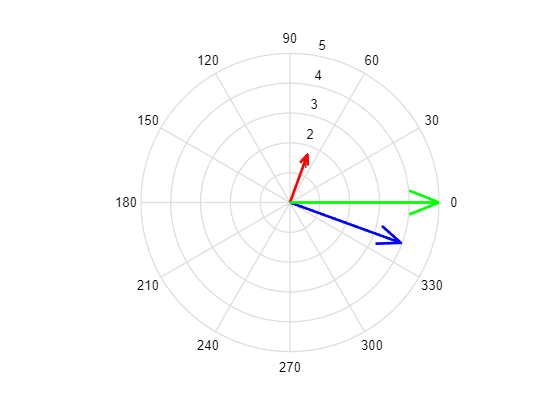

u = [real(vl) real(Il)*1e2 real(vf)];
v = [imag(vl) imag(Il)*1e2 imag(vf)];
co = compass(u,v);
c1 = co(1);
c1.LineWidth = 2;
c1.Color = 'r';
c2 = co(2);
c2.LineWidth = 2;
c2.Color = 'b';
c3 = co(3);
c3.LineWidth = 2;
c3.Color = 'g';

diagrama fasorial, tension de la fuente (verde), tension en el inductor (rojo), corriente en el indcutor (azul)

**DISEÑO 2**

**circuito RC diseño para 70° **

c = 1e-6;

syms angulo f C R

ec1 = solve(tan(angulo)==(1/(2*pi*f*C))/R,f)

$$ec1 = \frac{1}{2\,C\,R\,\pi \,\tan\left(\mathrm{angulo}\right)}$$

f = 1/(2*c*r*pi*tand(70)) %frecuencia necesaria

f =        487.81


verificamos en el simulador

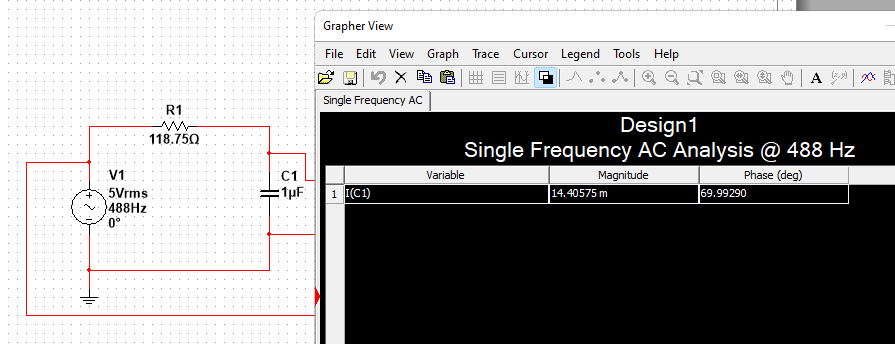

xc = -(1/(2*pi*f*c))*j

xc =             0 -     326.26i


zrc = r + xc

zrc =        118.75 -     326.26i


Ic = vf/zrc;
Ic_fasor = [abs(Ic) angle(Ic)*180/pi] %fasor corriente en el capacitor [A]

Ic_fasor =      0.014401           70


vc = Ic*(xc);
vc_fasor = [abs(vc) angle(vc)*180/pi] %fasor voltaje en el capacitor [V]

vc_fasor =        4.6985          -20


verificamos en el osciloscopio

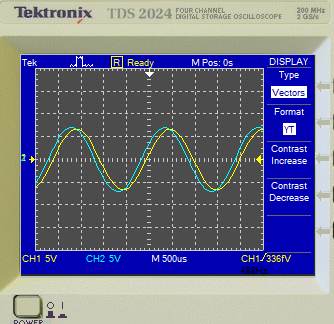

tension de la fuente (amarillo) comparada con la tension en el capacitor (azul)

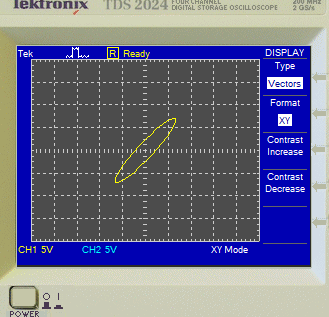

figura de lissajous

Diagrama fasorial

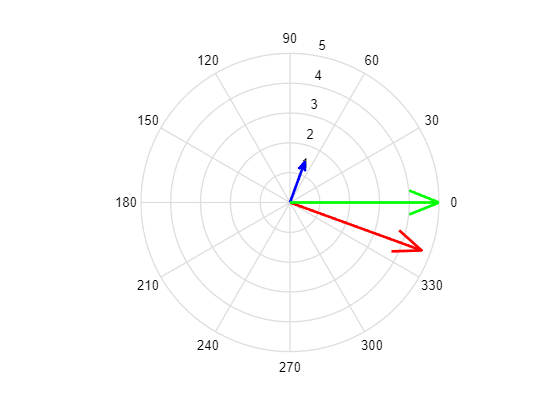

u = [real(vc) real(Ic)*1e2 real(vf)];
v = [imag(vc) imag(Ic)*1e2 imag(vf)];
co = compass(u,v);
c1 = co(1);
c1.LineWidth = 2;
c1.Color = 'r';
c2 = co(2);
c2.LineWidth = 2;
c2.Color = 'b';
c3 = co(3);
c3.LineWidth = 2;
c3.Color = 'g';

diagrama fasorial, tension de la fuente (verde), tension en el capacitor (rojo), corriente en el capacitor (azul)

**Circuito RC diseño para 20°**

f = 1/(2*c*r*pi*tand(20)) %frecuencia necesaria

f =        3682.3


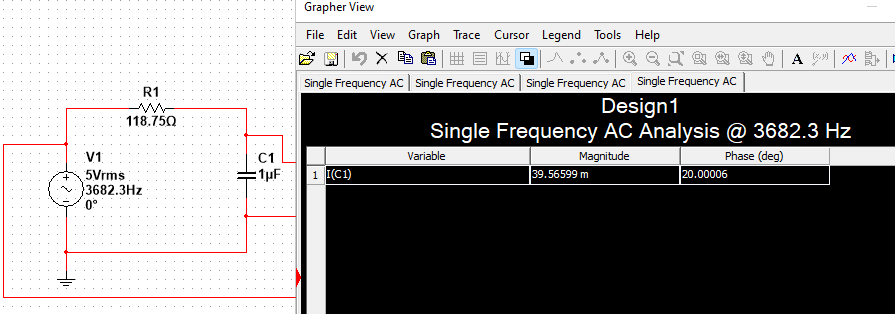

xc = -(1/(2*pi*f*c))*j

xc =             0 -     43.221i


zrc = r + xc

zrc =        118.75 -     43.221i


Ic = vf/zrc;
Ic_fasor = [abs(Ic) angle(Ic)*180/pi] %fasor corriente en el capacitor [A]

Ic_fasor =      0.039566           20


vc = Ic*(xc);
vc_fasor = [abs(vc) angle(vc)*180/pi] %fasor voltaje en el capacitor [V]

vc_fasor =        1.7101          -70


Verficamos en el simulador:

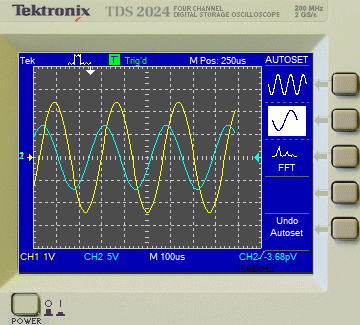

tension de la fuente (amarillo) comparada con la tension en el capacitor (azul)

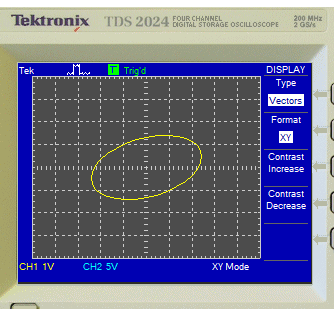

figura de lissajous

Diagrama fasorial

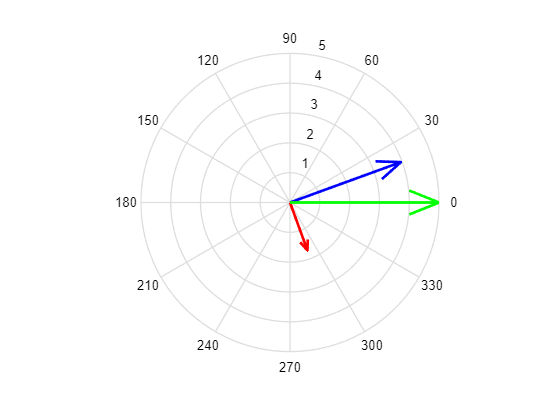

u = [real(vc) real(Ic)*1e2 real(vf)];
v = [imag(vc) imag(Ic)*1e2 imag(vf)];
co = compass(u,v);
c1 = co(1);
c1.LineWidth = 2;
c1.Color = 'r';
c2 = co(2);
c2.LineWidth = 2;
c2.Color = 'b';
c3 = co(3);
c3.LineWidth = 2;
c3.Color = 'g';

diagrama fasorial, tension de la fuente (verde), tension en el capacitor (rojo), corriente en el capacitor (azul)

**DISEÑO 3**

**Circuito RLC diseño**

syms angulo f L C R

frec = solve(tan(angulo)==((2*pi*f*L)-(1/(2*pi*f*C)))/R,f)

$$frec = \left(\begin{array}{c} \frac{\sqrt{C\,\left(C\,R^{2}\,{\tan\left(\mathrm{angulo}\right)}^{2}+4\,L\right)}+C\,R\,\tan\left(\mathrm{angulo}\right)}{4\,C\,L\,\pi }\\ -\frac{\sqrt{C\,\left(C\,R^{2}\,{\tan\left(\mathrm{angulo}\right)}^{2}+4\,L\right)}-C\,R\,\tan\left(\mathrm{angulo}\right)}{4\,C\,L\,\pi } \end{array}\right)$$

f1 = ( sqrt(c*(c*(r^2)*(tand(-70)^2)+4*l)) + (c*r*tand(-70)) )/(4*c*l*pi) %frecuencia para angulo de desfase positivo

f1 =        466.83


f2 = abs(-( sqrt(c*(c*(r^2)*(tand(-70)^2)+4*l)) - (c*r*tand(-70)) )/(4*c*l*pi)) %frecuencia para angulo de desfase negativo

f2 =         10852


verificamos en el simulador

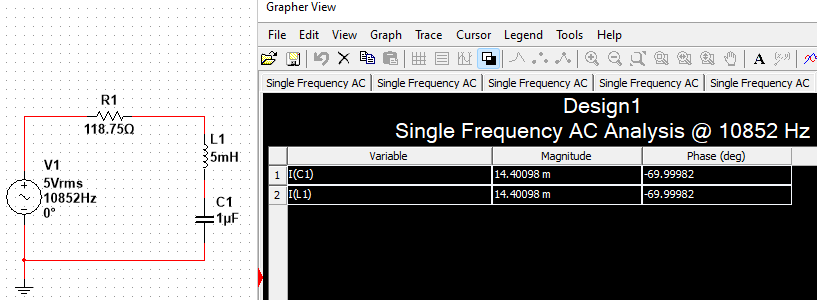

correinte con angulo de desfase **negativo (-70°)**

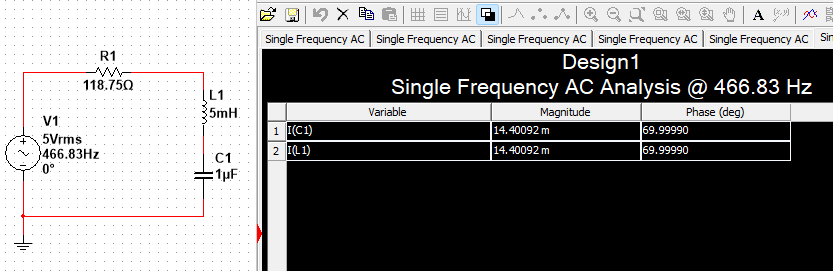

corriente con angulo de desfase **positivo (70°)**

Ahora calculamos las corrientes y tensiones en cada elemento reactivo para ambos diseños

***Angulo negativo:***

xl = (2*pi*f2*l)*j

xl =             0 +     340.93i


xc = -(1/(2*pi*f2*c))*j

xc =             0 -     14.666i


zrlc = r + xl + xc

zrlc =        118.75 +     326.26i


Irlc = vf/zrlc;
Irlc_fasor = [abs(Irlc) angle(Irlc)*180/pi] %fasor corriente en el circuit rlc [A]

Irlc_fasor =      0.014401          -70


vl = Irlc*(xl);
vl_fasor = [abs(vl) angle(vl)*180/pi] %fasor voltaje en el inductor

vl_fasor =        4.9097           20


vc = Irlc*(xc);
vc_fasor = [abs(vc) angle(vc)*180/pi] %fasor voltaje en el capacitor

vc_fasor =        0.2112         -160


verificamos en el osciloscopio

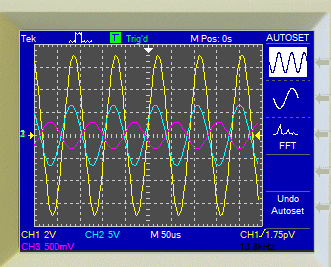

tension de la fuente (amarillo) comparada con la tension en el inductor (azul) y la tension en el capacitor (violeta)

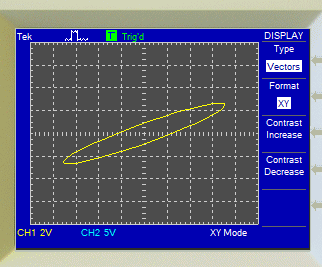

figura de lissajous

diagrama fasorial

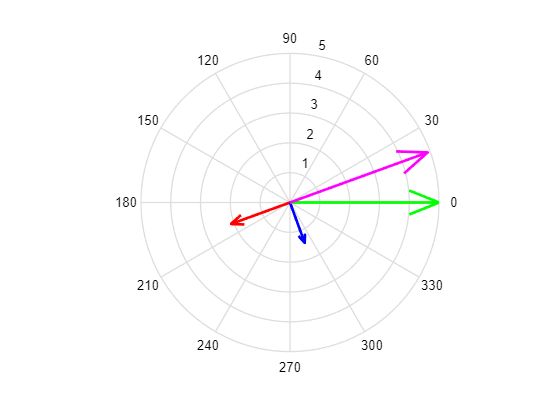

u = [real(vc)*10 real(Irlc)*1e2 real(vf) real(vl)];
v = [imag(vc)*10 imag(Irlc)*1e2 imag(vf) imag(vl)];
co = compass(u,v);
c1 = co(1);
c1.LineWidth = 2;
c1.Color = 'r';
c2 = co(2);
c2.LineWidth = 2;
c2.Color = 'b';
c3 = co(3);
c3.LineWidth = 2;
c3.Color = 'g';
c4 = co(4);
c4.LineWidth = 2;
c4.Color = 'magenta';

Diagrama fasorial, tension de la fuente (verde), tension en el capacitor (rojo), corriente en el circuito (azul), tension en el inductor (magenta)

**Angulo positivo:**

xl = (2*pi*f1*l)*j

xl =             0 +     14.666i


xc = -(1/(2*pi*f1*c))*j

xc =             0 -     340.93i


zrlc = r + xl + xc

zrlc =        118.75 -     326.26i


Irlc = vf/zrlc;
Irlc_fasor = [abs(Irlc) angle(Irlc)*180/pi] %fasor corriente en el circuito rlc [A]

Irlc_fasor =      0.014401           70


vl = Irlc*(xl);
vl_fasor = [abs(vl) angle(vl)*180/pi] %fasor voltaje en el inductor

vl_fasor =        0.2112          160


vc = Irlc*(xc);
vc_fasor = [abs(vc) angle(vc)*180/pi] %fasor voltaje en el capacitor

vc_fasor =        4.9097          -20


verificamos en el simulador

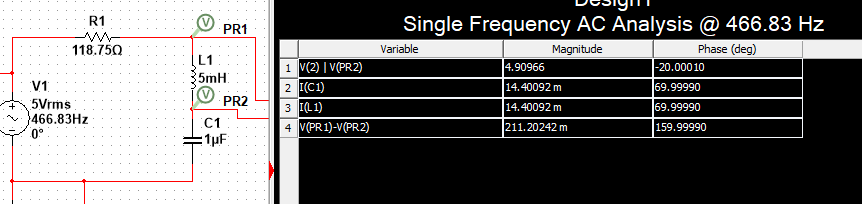

verificamos en el osiloscopio

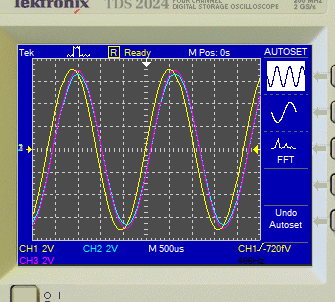

tension de la fuente (amarillo) comparada con la tension en el inductor (azul) y la tension en el capacitor (violeta)

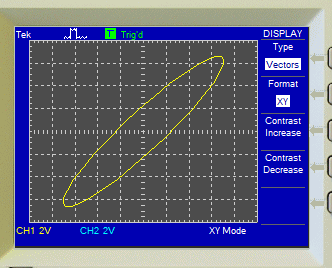

figura de lissajois

Diagrama fasorial

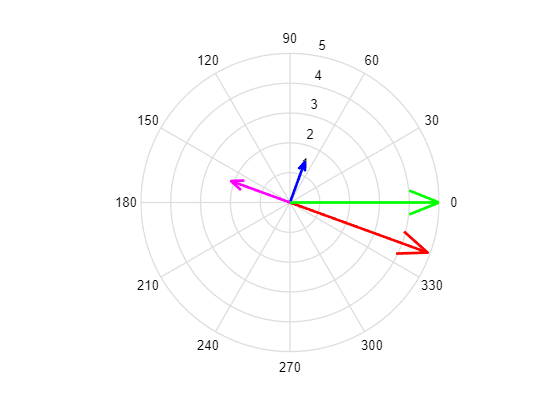

u = [real(vc) real(Irlc)*1e2 real(vf) real(vl)*10];
v = [imag(vc) imag(Irlc)*1e2 imag(vf) imag(vl)*10];
co = compass(u,v);
c1 = co(1);
c1.LineWidth = 2;
c1.Color = 'r';
c2 = co(2);
c2.LineWidth = 2;
c2.Color = 'b';
c3 = co(3);
c3.LineWidth = 2;
c3.Color = 'g';
c4 = co(4);
c4.LineWidth = 2;
c4.Color = 'magenta';

Diagrama fasorial, tension de la fuente (verde), tension en el capacitor (rojo), corriente en el circuito (azul), tension en el inductor (magenta)